## Get Everything Ready to Go

first clear workspace

clear all
close all
clc
currentFolder = '/Users/alysolberg/Dropbox (HMS)/hyperData';
saveFolder = '/Users/alysolberg/Library/Mobile Documents/com~apple~CloudDocs/MATLAB/livelovehochbaum';
cd(currentFolder);
load CompiledPhysio_final.mat

## Reconfiguring Tables to Join

  1.Temp

ID=tempMasterData.Properties.RowNames;
IDa = cell2table(ID);
IDa.Properties.RowNames = ID;
tempmasterII=[IDa tempMasterData];
tempmasterII.Properties.VariableNames{'ID'}='Master_ID';
tempmasterII.Properties.VariableNames = {'Master_ID' 'OriginalID' 'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'};
dataprestack=join(tempmasterII,masterID);
dataprestack = removevars(dataprestack,{'OriginalID' 'Spreadsheet' 'ImportantNotes' 'Var14' 'Var15' 'Var16' 'Var17' 'Var18' 'Var19' 'Var20'})

dataprestack = 261×23 table
           Master_ID    Day01H    Day02H    Day03H    Day04T    Day05T    Day06T    Day07T    Day08T    Day09T    Day10T    Day11T    Day12T      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round
           _________    ______    ______    ______    ______    ______    ______    ______    

2. Weight

weightmasterII=[IDa weightMasterData];
weightmasterII.Properties.VariableNames = {'Master_ID' 'OriginalID' 'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'}

weightmasterII = 261×14 table
           Master_ID       OriginalID       Day01H    Day02H    Day03H    Day04T    Day05T    Day06T    Day07T    Day08T    Day09T    Day10T    Day11T    Day12T
           _________    ________________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    H1      {'H1' }     {'Control_1Inj'}     NaN        NaN      24.1      24.5      24.5      24.4      NaN       NaN       NaN       NaN       NaN      

3. Food

foodmasterII=[IDa deltaFoodData];
foodmasterII.Properties.VariableNames = {'Master_ID' 'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'}

foodmasterII = 261×13 table
           Master_ID    Day01H    Day02H    Day03H    Day04T    Day05T    Day06T    Day07T    Day08T    Day09T    Day10T    Day11T    Day12T
           _________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    H1      {'H1' }      NaN       NaN       NaN       4.3       4.1       3.7       NaN       NaN       NaN       NaN       NaN       NaN  
    H2      {'H2' }      NaN       NaN       NaN       3.9       4.9    

## Stacking Data Tables

prelimstack=stack(dataprestack,{'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'})

prelimstack = 3132×13 table
             Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round    Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09_1    Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_
             _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _____________________________________    <

weightstack=stack(weightmasterII,{'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'})

weightstack = 3132×4 table
             Master_ID       OriginalID       Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09_1    Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_
             _________    ________________    _______________________________________________________________    _______________________________________________________________

    H1        {'H1'}      {'Control_1Inj'}                                Day01H                                                               NaN                              
    H1_1      {'H1'}      {'Control_1Inj'}                                Day02H                                                               NaN                              
    H1_2      {'H1'}      {'Control_1Inj'}                                Day

foodstack=stack(foodmasterII,{'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'})

foodstack = 3132×3 table
             Master_ID    Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09_1    Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_
             _________    _______________________________________________________________    _______________________________________________________________

    H1        {'H1'}                                  Day01H                                                               NaN                              
    H1_1      {'H1'}                                  Day02H                                                               NaN                              
    H1_2      {'H1'}                                  Day03H                                                               NaN                              
    H1_3      {'H1'

## Reconfiguring Stacks to Join

prelimstack.Properties.VariableNames{'Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_'}='Temp';
prelimstack.Properties.VariableNames{'Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09_1'}='Day';
weightstack.Properties.VariableNames{'Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_'}='Weight';
foodstack.Properties.VariableNames{'Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_'}='Food';

foodstack.Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09_1=[];
foodstack.Master_ID=[];
weightstack.Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09_1=[];
weightstack.Master_ID=[];
weightstack.OriginalID=[];

## Joining Stacks

alldataprelim = [prelimstack,foodstack];
alldata = [alldataprelim,weightstack]

alldata = 3132×15 table
             Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round     Day      Temp    Food    Weight
             _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _____________________________________    _____    ______    ____

alldataII=stack(alldata,{'Condition_H_C_'})

alldataII = 3132×16 table
             Master_ID      Original_ID       Genotype    Sex_M_F_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round     Day      Temp    Food    Weight    Condition_H_C__Indicator    Condition_H_C_
             _________    ________________    ________    ________    _____________________________    ______________    _________________    _______________    _____________________________________    _____    ______    

## Making Graphs

1.Temp

a=gramm('x',alldataII.Day,'y',alldataII.Temp,'color',alldataII.Condition_H_C_)

a =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


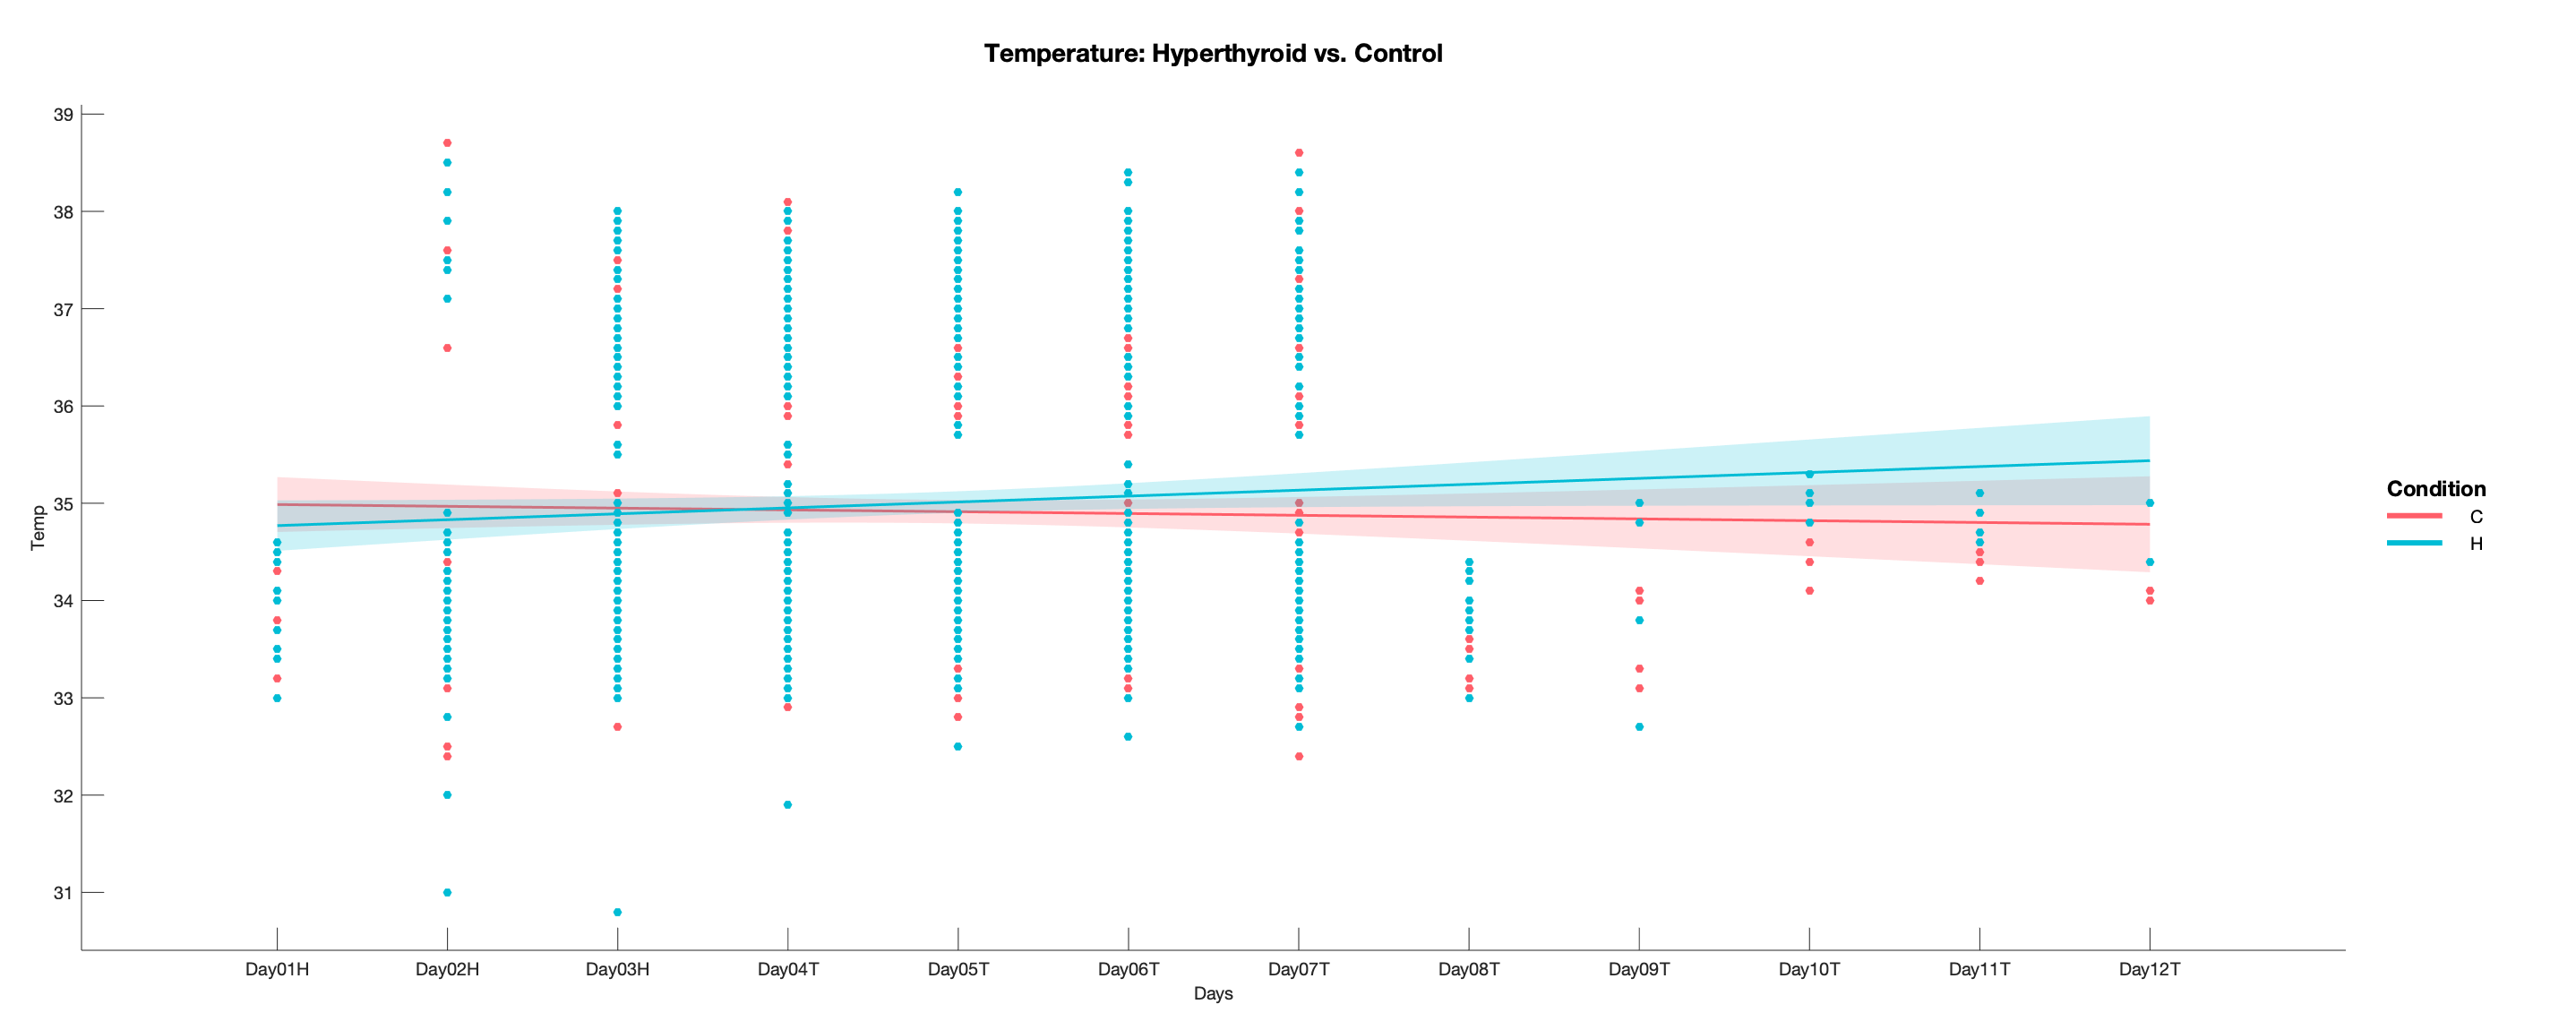

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


a.geom_point();
a.stat_glm();
a.set_names('x','Days','y','Temp','color','Condition');
a.set_title('Temperature: Hyperthyroid vs. Control');
figure('Position',[100 100 2000 800]);
a.draw()

2. Food Intake

a=gramm('x',alldataII.Day,'y',alldataII.Food,'color',alldataII.Condition_H_C_)

a =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


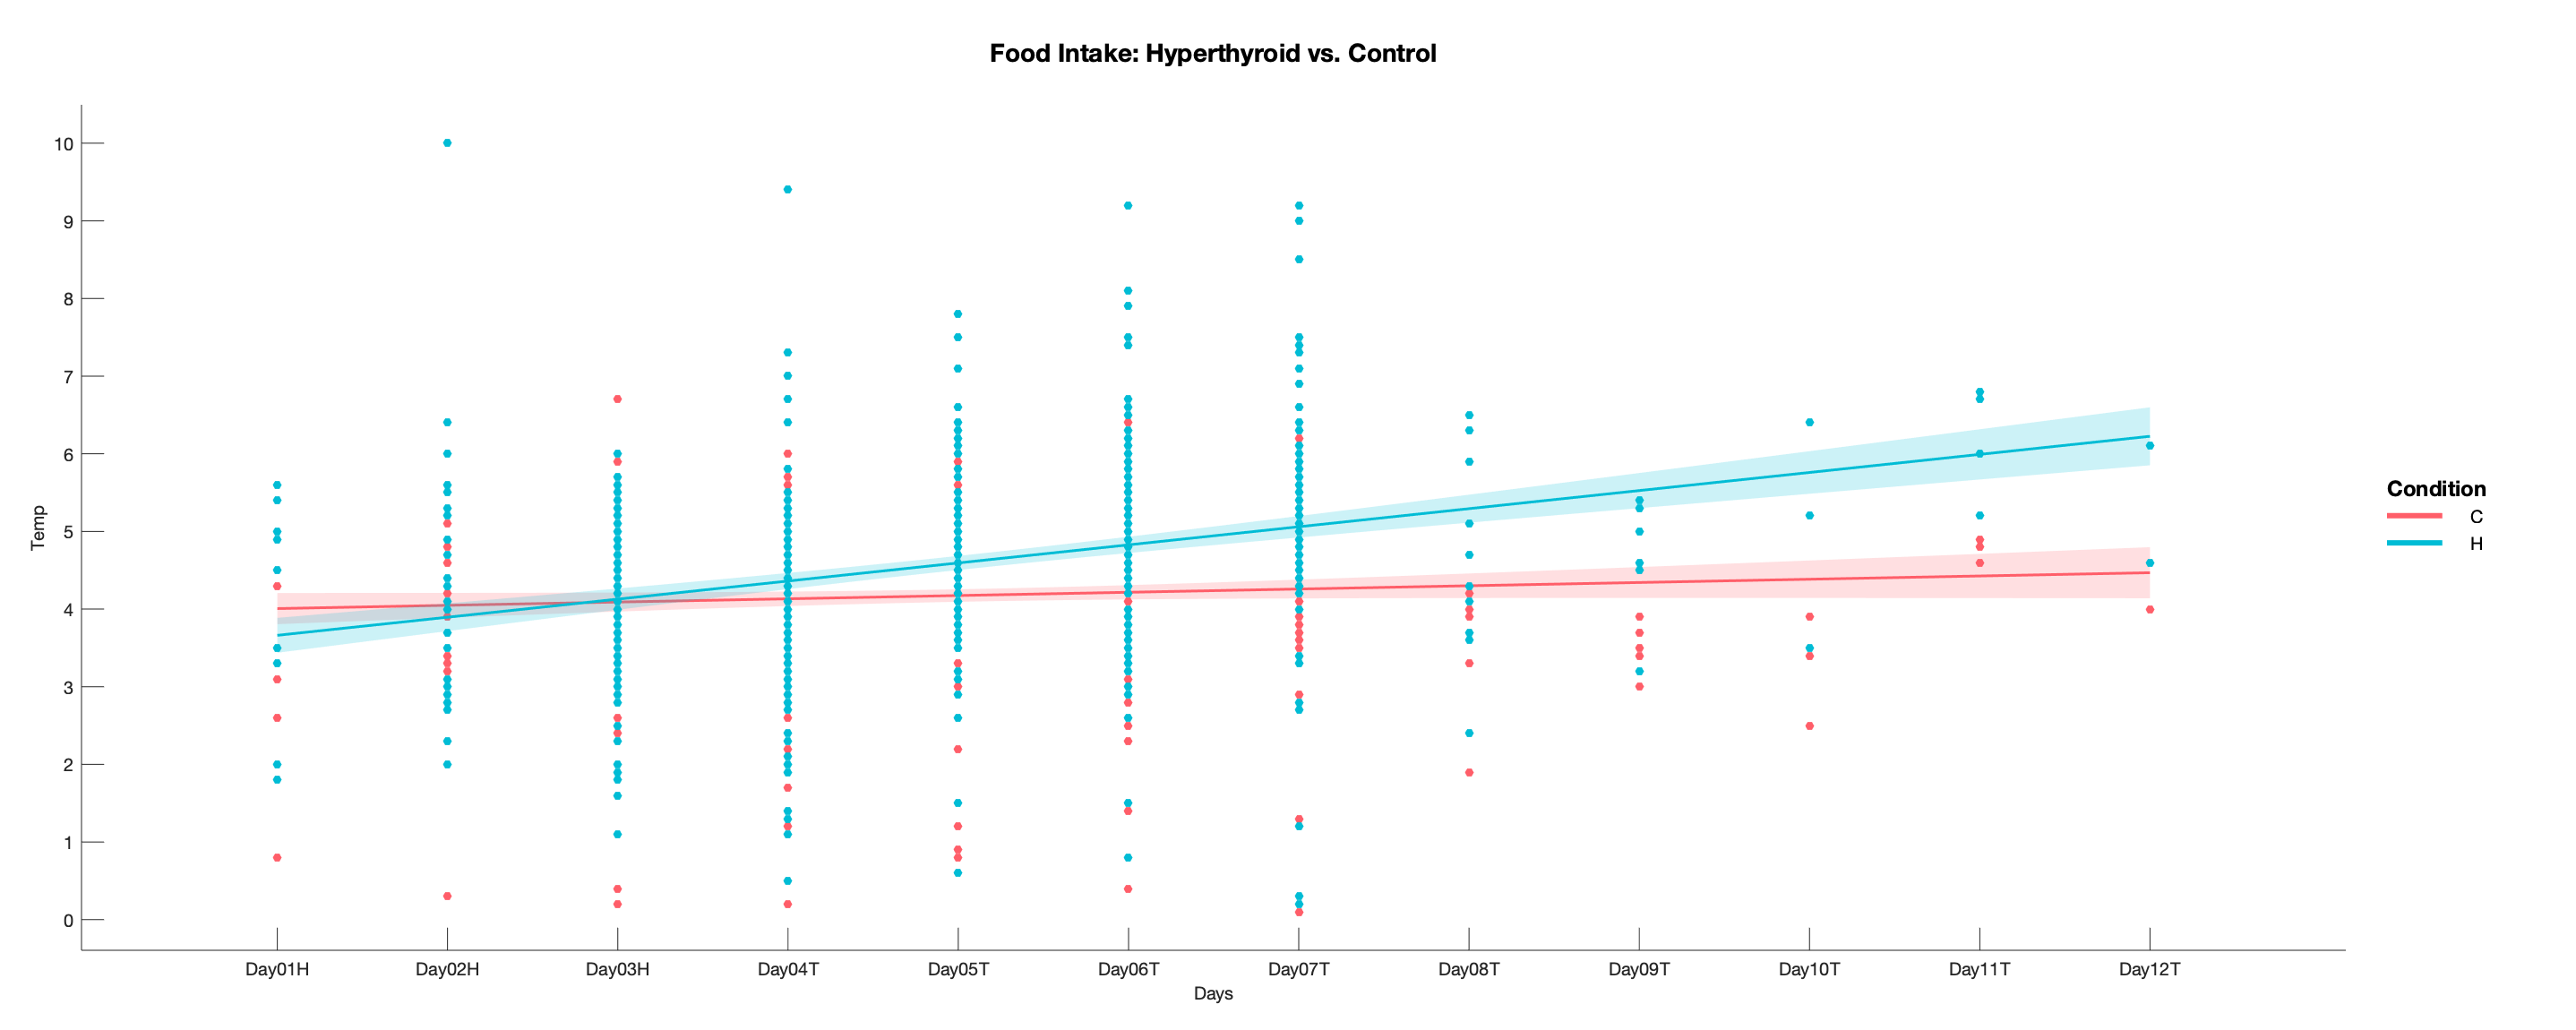

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


a.geom_point();
a.stat_glm();
a.set_names('x','Days','y','Temp','color','Condition');
a.set_title('Food Intake: Hyperthyroid vs. Control');
figure('Position',[100 100 2000 800]);
a.draw()

3. Weight

a=gramm('x',alldataII.Day,'y',alldataII.Weight,'color',alldataII.Condition_H_C_)

a =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


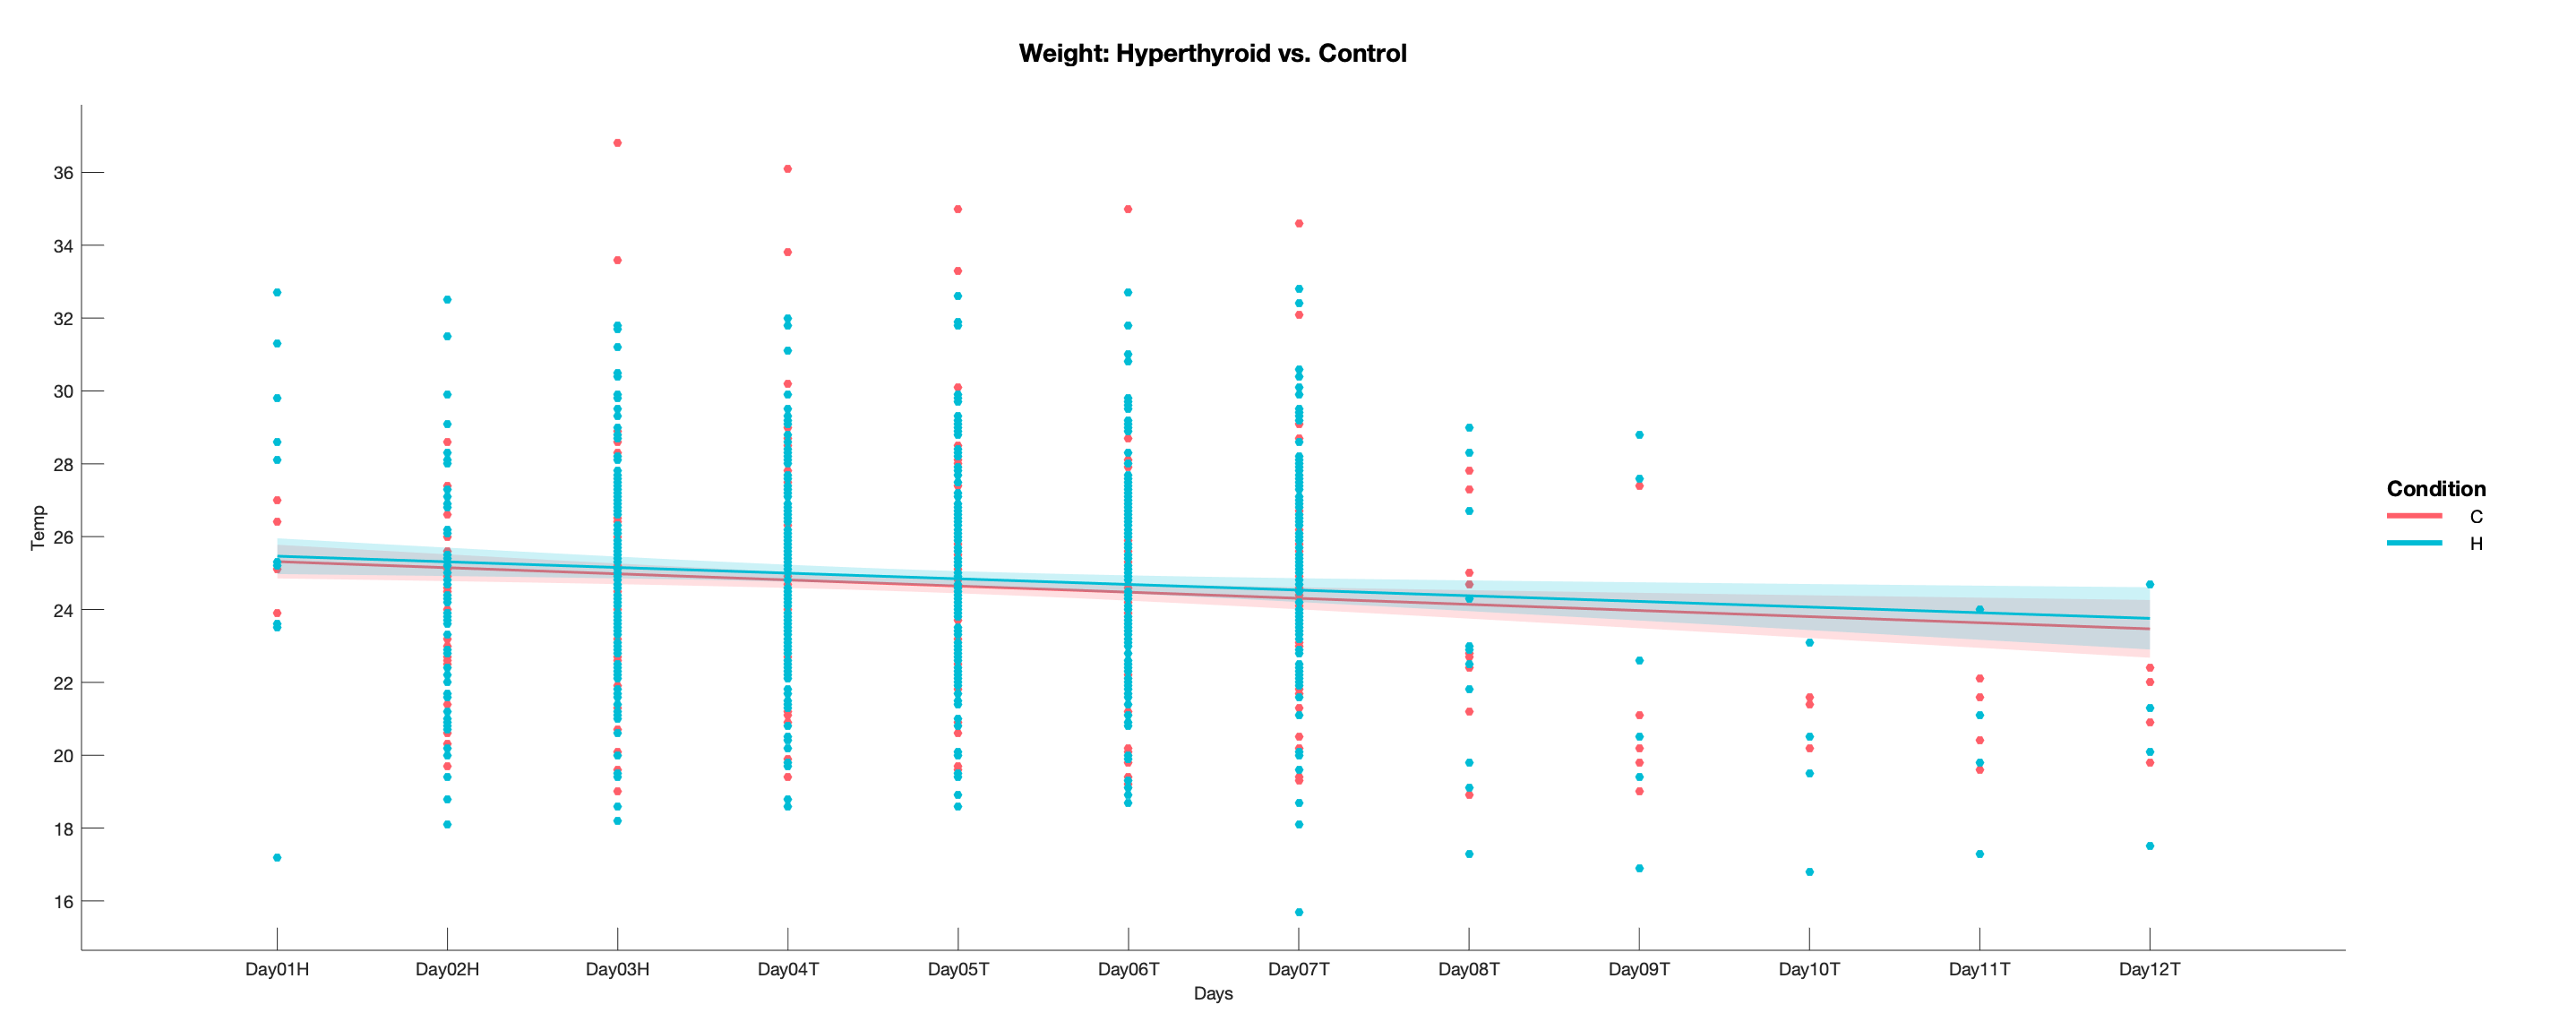

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


a.geom_point();
a.stat_glm();
a.set_names('x','Days','y','Temp','color','Condition');
a.set_title('Weight: Hyperthyroid vs. Control');
figure('Position',[100 100 2000 800]);
a.draw()